# Площадь поверхности

Пусть есть некая поверхность, которая задана функцией $f(x, y)$ на органниченной области $D$ в прямоугольных координатах.

Тогда площадь этой поверхности можно вычислить с помощью следующего двойного интеграла:


$$S= \int\int_D \sqrt{1+ \left( \frac{\partial{f}}{\partial{x}} \right)^2 + \left( \frac{\partial{f}}{\partial{y}} \right)^2}\,dx\,dy$$


## Пример

Поверхность задана функцией $f$:


$$f(x, y) = \cos^2 (x y) + 2 \ln(x^2 y^2) - x^3 y$$


Область $D$ задана как интревалы по координатам $x$ и $y$:


$$D: \ x \in \left[-2, -\frac{1}{2}\right], \ y \in [-2, -1]$$


Таким образом, исходный двойной интеграл можно считать как повторный (в повторных интегралах сначала находится внутренний интеграл, а затем - внешний).


$$S = \int_{y_1}^{y_2} \int_{x_1}^{x_2} \sqrt{1+ \left( \frac{\partial{f}}{\partial{x}} \right)^2 + \left( \frac{\partial{f}}{\partial{y}} \right)^2}\,dx\,dy$$


### 1. Определение основных объектов

syms x y; % объявляем символы 'x' и 'y'

% символьное выражение для функции f(x,y):
f = cos(x*y)^2 + 2*log((x^2)*(y^2)) - (x^3)*y

$$f = 2\,\log\left(x^{2}\,y^{2}\right)+{\cos\left(x\,y\right)}^{2}-x^{3}\,y$$


% границы области D
Dx = [-2 -1/2];
Dy = [-2 -1];

### 2. Визуализация поверхности

Этот шаг выполнять не обязательно, но полезно для понимания задачи

% готовим координатную сетку для визуализации
ix = linspace(Dx(1), Dx(2), 31);
iy = linspace(Dy(1), Dy(2), 21);
[ix, iy] = meshgrid(ix, iy);

% конвертируем символьное выражение в matlab-функцию
ffunc = matlabFunction(f)

ffunc = function_handle with value:
    @(x,y)log(x.^2.*y.^2).*2.0+cos(x.*y).^2-x.^3.*y


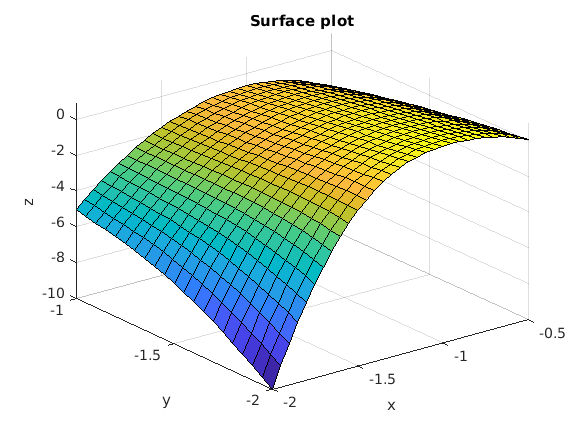


% стоим трёхмерный график
iz = ffunc(ix, iy);
surf(ix, iy, iz);
title('Surface plot');
xlabel('x');
ylabel('y');
zlabel('z');

### 3. Вычисление площади поверхности

Для вычисления площади поверхности по формуле, заданной выше, нам понадобятся выражения для частных производных функции $f$ по $x$ и $y$. 

dfx = diff(f, x) % частная производная f по x

$$dfx = \frac{4}{x}-3\,x^{2}\,y-2\,y\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)$$

dfy = diff(f, y) % частная производная f по x

$$dfy = \frac{4}{y}-x^{3}-2\,x\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)$$


% подынтегральная функция в формуле площади
s = sqrt(1 + power(dfx, 2) + power(dfy, 2))

$$s = \sqrt{{\left(x^{3}-\frac{4}{y}+2\,x\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)\right)}^{2}+{\left(3\,x^{2}\,y-\frac{4}{x}+2\,y\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)\right)}^{2}+1}$$


% matlab умеет интегрировать только по одной переменной
% чтобы посчитать двойной интеграл,
% используем последовательное интегрирование
% по каждой переменной
S = int( int(s, x, Dx) , y, Dy)

$$S = \int_{-2}^{-1}\int_{-2}^{-\frac{1}{2}}\sqrt{{\left(x^{3}-\frac{4}{y}+2\,x\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)\right)}^{2}+{\left(3\,x^{2}\,y-\frac{4}{x}+2\,y\,\cos\left(x\,y\right)\,\sin\left(x\,y\right)\right)}^{2}+1}\mathrm{d}x\mathrm{d}y$$


% Если 'int' не может посчитать
% определённый интеграл аналитически, 
% мы можем посчитать численное приближение
% функцией 'vpa' (Variable-precision arithmetic)
Svpa = vpa(S)

$$Svpa = 9.0952059125844497523352422008676$$

В этом примере площадь заданной поверхности составляет примерно $9.1$